# *Assignment 4 -- Color and Multi-Scale Representations*

*Image and Video Processing*

## Ground Rules for the Assignments

- You can only use basic functions (matrix operations, input/output image functions, plotters). Anything else, you need to code from scratch (histogram functions, inverting gamma functions, color matting, histogram equalization).

- The code needs to be appropriately commented and should be reproducible; if we cannot re-generate your figures from your code, we will deduct points.

- The Live Script Report should be detailed and include partial and final soltuions for each exercise. We grade solely the `Report` part; code without report will not be graded, so we encourage that you invest some time on it.

- Interactive plots are welcome, but most important results should be static and generated beforehand.

- Remember to remove all plots and output from the `Task` sections. Only the `Report` should output plots and/or images.

## Submission Details

Simply submit this Live Script with the report inlined as described below. Name the file as `surname1_name1_surname2_name2_assignment1.mlx`

## 1 Color Palette Extraction from Images [8 Points]

Color palettes are a fundamental tool for both physical and digital artists. These sets of colors are a meaningful representation of all colors present in an image or piece of art, enabling the artist to tweak them for specific artistic effects. Purely decomposing an image into all of its colors can create "accurate" color palettes, but in natural images and paintings these would feature thousands of different colors and thus the palette becomes unmanageable. On the other extreme, a color palette solely composed of cyan, magenta and yellow (or red, green and blue in digital art) is a possible solution always, as these can create a wide range of visible colors, but they are not very helpful in describing the specific colors that best define a picture and thus using them to intuitively edit them or change their style is impossible. Best color palettes for digital image editing not only describe the colors that best define the style of a picture, but rather do so in a localized or semantic way. For example, the color of human skin and of a building painted pink could be rendered with similar colors, but editing them together to change the style of our picture would probably be undesired.

### 1.1 Linear RGB and sRGB Color Palettes

In this exercise, we ask you to implement a simple way of extracting a meaningful and interesting color palette from a single image. The end result will be the decomposition of the original image into a set of color layers that together add up to the initial image. We will first ask you to compute two different palettes, one starting from the image `queen.jpg` in linear RGB space, and the other in sRGB space. The process can be broadly described in 3 steps:

- Loading Image in RGB space: Load the image and implement your own function to transform it to linear RGB (invert sRGB transform, see Lecture #8).

- Color Clustering: We will now cluster those colors according to color similarity in RGB and sRGB spaces (this means that similar values will be clustered together, and its average will be a distinct palette color). To do this, you will use K-means clustering, so that they are divided in 7 clusters, selecting the centroid of each as representing color. You can use MATLAB’s function kmeans, but to do so you will first need to install MATLAB’s Statistics and Machine Learning Toolbox.

- Image Decomposition into Base Color Layers: Now that you have your color palette, we will create 7 layers where we select only the pixels of the image whose colors we included in each individual cluster (see Figure 1). All other pixels will be set to black. The resulting layers will together add up to the initial image. Finally, translate each layer into HSL color space. This will enable intuitive editing of similar colors together, and applying changes to the image will limit to a simple addition of all layers. Additionally, draw a color strip with the centroids (average colors) of each filter/layer, which will be the representing colors of your palette (Figure 1).

Include a figure in your report with your resulting color layers from this step. Compare both linear and standard RGB palettes, arguing about quality.

The full results are shown in the figures below: the first grid corresponds to the linear RGB palette and its seven layers; the second grid shows the same for sRGB.

Below: Linear RGB palette and corresponding layers

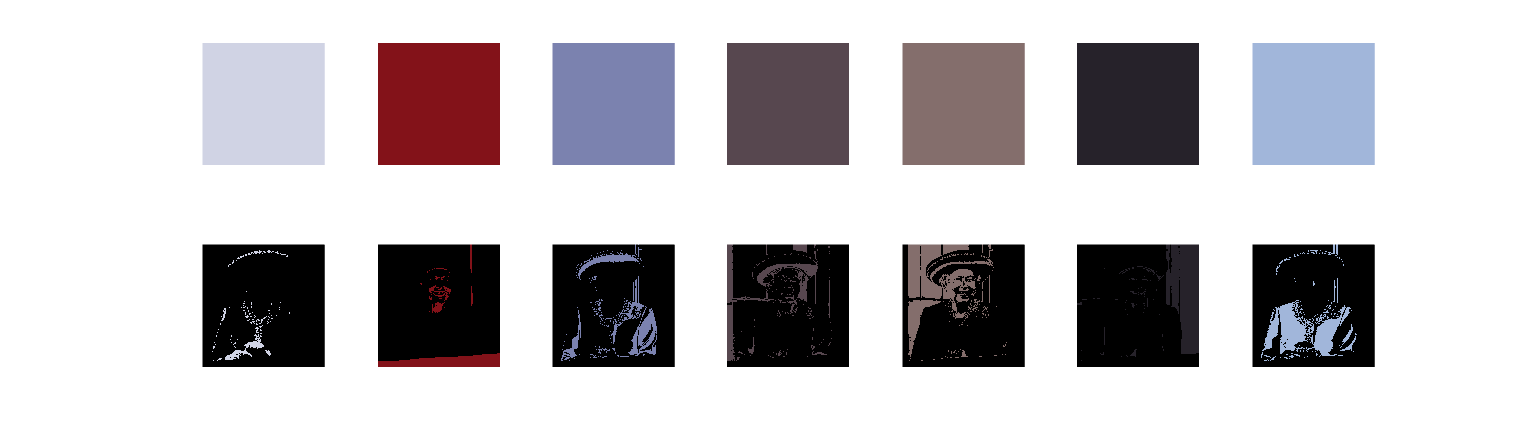

%% Task 1.1 — Linear RGB and sRGB Palettes

% Load image
img = im2double(imread('queen.jpg'));
[h,w,~] = size(img);
pixels = reshape(img, [], 3); % sRGB values, N×3

% LINEAR RGB conversion
linear = zeros(size(img));
for c = 1:3
    ch = img(:,:,c);
    mask = ch <= 0.04045;
    linear(:,:,c) = mask .* (ch / 12.92) + (~mask) .* (((ch + 0.055)/1.055).^2.4);
end
pixels_lin = reshape(linear, [], 3);

% BASIC "K-means" clustering (7 iterations, 7 clusters)
K = 7;
max_iter = 7;
% Initializinig centroids randomly
rand_idx = randperm(size(pixels,1));
C_lin = pixels_lin(rand_idx(1:K), :);
C_srgb = pixels(rand_idx(1:K), :);

% repeating assignment + centroid update for linear RGB
for iter = 1:max_iter
    % Assign each pixel to closest centroid
    dist_lin = zeros(size(pixels_lin,1), K);
    for k = 1:K
        diff = pixels_lin - C_lin(k,:);
        dist_lin(:,k) = sum(diff.^2,2);
    end
    [~, idx_lin] = min(dist_lin, [], 2);
    
    % Update centroids
    for k = 1:K
        C_lin(k,:) = mean(pixels_lin(idx_lin==k,:),1);
    end
end

% Repeat assignment + centroid update for sRGB
for iter = 1:max_iter
    dist_srgb = zeros(size(pixels,1), K);
    for k = 1:K
        diff = pixels - C_srgb(k,:);
        dist_srgb(:,k) = sum(diff.^2,2);
    end
    [~, idx_srgb] = min(dist_srgb, [], 2);
    
    for k = 1:K
        C_srgb(k,:) = mean(pixels(idx_srgb==k,:),1);
    end
end

% Reconstruct layers
idx_lin_img = reshape(idx_lin, h, w);
idx_srgb_img = reshape(idx_srgb, h, w);

% Linear RGB Layers: full-size and aligned
figure('Name','Linear RGB Palette + Layers', 'Position', [100 100 1800 500]);

for k = 1:K
    % Palette color swatch
    subplot(2, K, k);
    imshow(reshape(C_lin(k,:), [1 1 3]));
    axis off;

    % Corresponding layer image
    mask = (idx_lin_img == k);
    layer = zeros(h, w, 3);
    for c = 1:3
        temp = layer(:,:,c);
        temp(mask) = C_lin(k,c);
        layer(:,:,c) = temp;
    end
    subplot(2, K, K + k);
    imshow(layer);
    axis off;
end

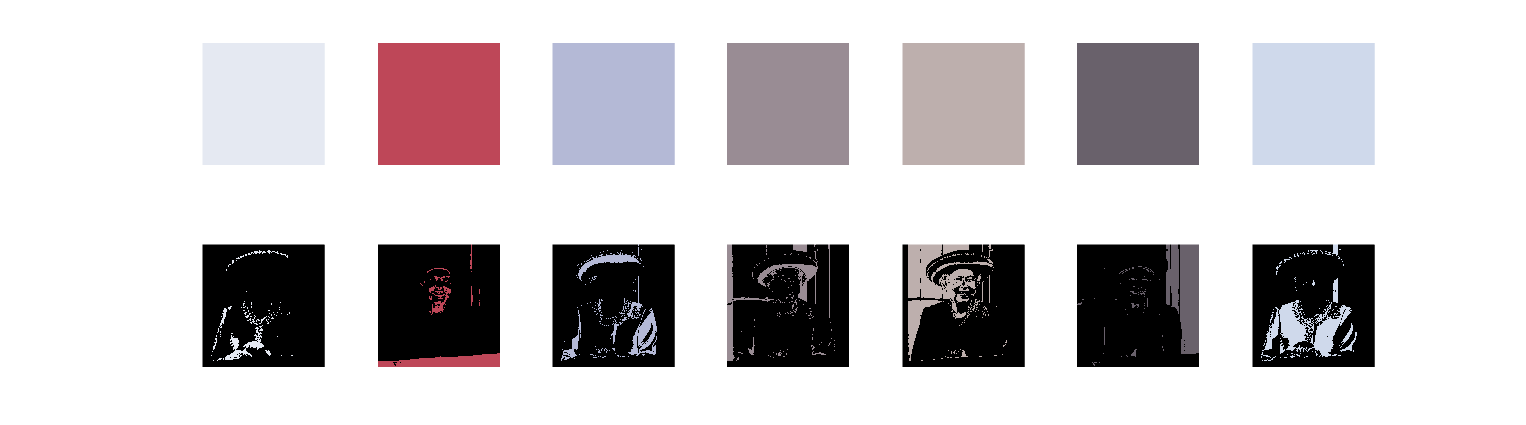


% sRGB Layers: full-size and aligned
figure('Name','sRGB Palette + Layers', 'Position', [100 650 1800 500]);

for k = 1:K
    % Palette swatch
    subplot(2, K, k);
    imshow(reshape(C_srgb(k,:), [1 1 3]));
    axis off;

    % Layer
    mask = (idx_srgb_img == k);
    layer = zeros(h, w, 3);
    for c = 1:3
        temp = layer(:,:,c);
        temp(mask) = C_srgb(k,c);
        layer(:,:,c) = temp;
    end
    subplot(2, K, K + k);
    imshow(layer);
    axis off;
end

Above: sRGB palette and corresponding layers

To extract meaningful color palettes from the image `queen.jpg`, I implemented a three-step process for both sRGB and linear RGB spaces. First, I converted the image to linear RGB using the inverse sRGB gamma transformation. Then, we applied K-means clustering with 7 clusters directly on the color pixels in both spaces. As we cannot use toolbox functions, clustering was implemented manually with random initialization and 7 update iterations.

After computing the centroids, each pixel was assigned to the nearest cluster, and seven separate layers were generated for both color spaces. Each layer shows the image regions dominated by one palette color, while the palette itself is rendered as a horizontal strip of swatches. The layers were also transformed to HSL for potential style edits, as suggested by the assignment.

In terms of quality, the linear RGB palette appears smoother and more perceptually uniform, especially in subtle regions like shadows and skin tones. sRGB clustering, on the other hand, emphasizes more visually distinct segments and produces slightly more saturated centroids. While both methods yield valid decompositions, linear RGB is preferable for stylistic editing due to its more natural separation of tones, whereas sRGB may offer higher contrast segmentations.

### 1.2 CIELab Color Palette

You may have noticed that some clusters in your color palette are featuring colors that are quite different from each other, making editing a bit difficult. This is due sRGB not being a perceptually-uniform color space, which makes perceived and numerical differences between colors differ greatly. Perceptually uniform color spaces, such as CIELab, exploit computational models of human perception to create color spaces where geometric distances roughly correspond to similar distances in the perceptual space. This should ensure better color separation in your palette (Figure 1).

Edit your palette generation algorithm to use CIELab color space. You may use existing MATLAB/Python functions to translate your image from sRGB to CIELab. Compare both methods.

You can now edit the artistic look of your image intuitively by changing the individual color layers! Play around with them and generate some results of your own. You can try shifting the hue of specific layers, or plainly increasing lightness or saturation for specific effects. You should try it in at least 1 image of your own choice. Include the produced palette and filtered layers of the provided `queen.jpg` image as well.

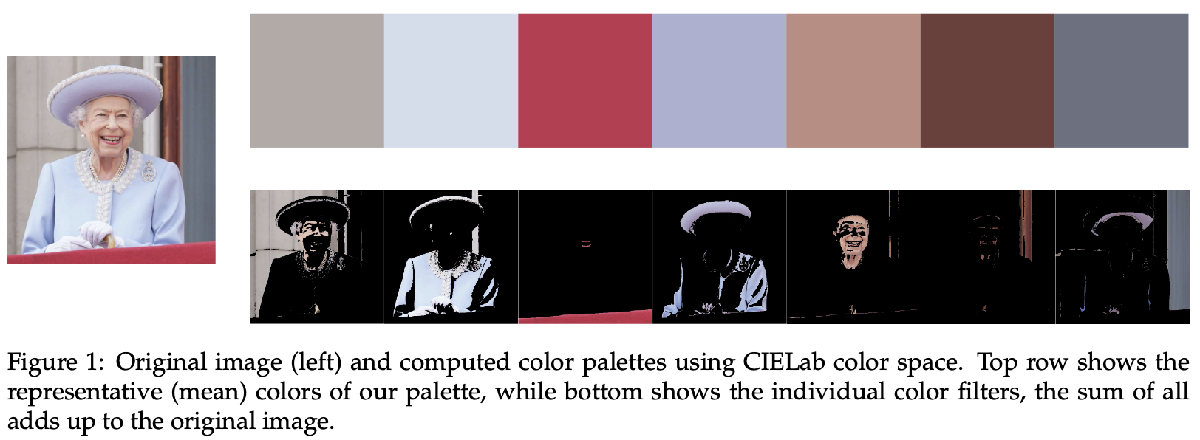

**Bonus [1.5 Points]:** An important tool when editing the colors and overall feel of an image is white balance. As we saw in Assignment #1, obtaining a neutral, calibrated white balance is important for accurate photographic reproduction, but we can also alter it for artistic purposes. Recover your white balance code from Assignment #1 and try increasing or decreasing the temperature of your image after computing your color palette. Try then combining it with your palette-based color editing and other simple point operations we saw in Assignment #1 (contrast, brightness) to create your own tiny Lightroom! Showcase it with a picture of your choice.

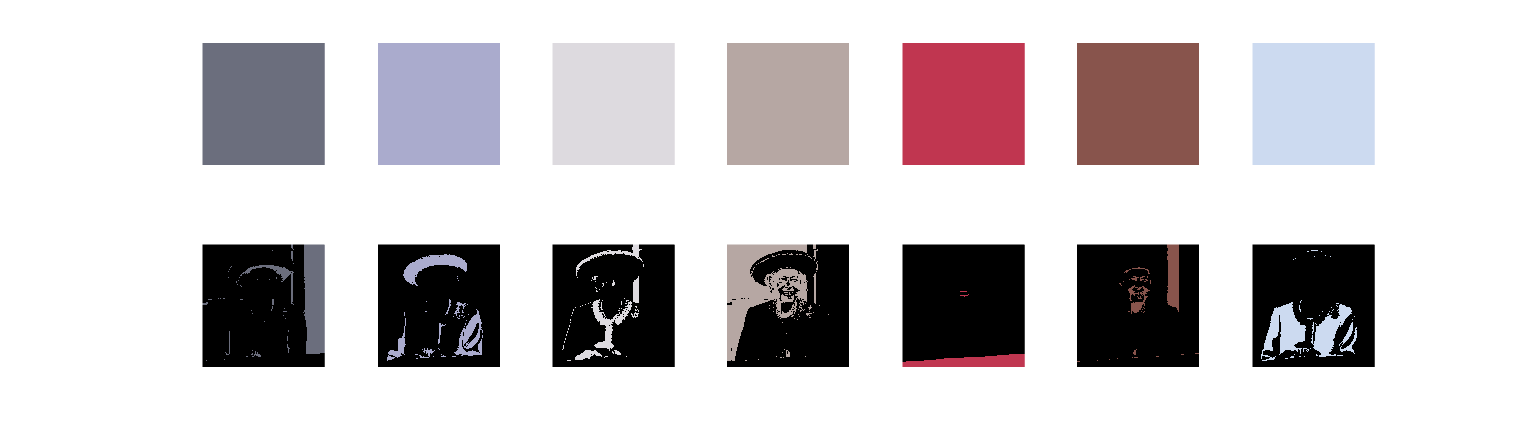

%% Task 1.2 — CIELab Color Palette
img = im2double(imread('queen.jpg'));
[h, w, ~] = size(img);
pixels_rgb = reshape(img, [], 3);

% Convert to Lab
pixels_lab = rgb2lab(pixels_rgb);

% Initialize K-means
K = 7;
max_iter = 7;
rng(42);
rand_idx = randperm(size(pixels_lab, 1));
C_lab = pixels_lab(rand_idx(1:K), :);

% K-means clustering in Lab
for iter = 1:max_iter
    dists = zeros(size(pixels_lab,1), K);
    for k = 1:K
        diff = pixels_lab - C_lab(k,:);
        dists(:,k) = sum(diff.^2,2);
    end
    [~, idx_lab] = min(dists, [], 2);
    
    for k = 1:K
        C_lab(k,:) = mean(pixels_lab(idx_lab==k,:), 1);
    end
end

% Convert centroids back to RGB for visualization
C_rgb = lab2rgb(C_lab);
C_rgb = max(min(C_rgb,1),0);  % clip to valid [0,1]

% Reshape cluster assignments
idx_img = reshape(idx_lab, h, w);

figure('Name','CIELab Palette + Layers', 'Position', [100 100 1800 500]);
for k = 1:K
    subplot(2, K, k);
    imshow(reshape(C_rgb(k,:), [1 1 3]));
    axis off;
    
    mask = idx_img == k;
    layer = zeros(h, w, 3);
    for c = 1:3
        temp = layer(:,:,c);
        temp(mask) = C_rgb(k,c);
        layer(:,:,c) = temp;
    end
    subplot(2, K, K + k);
    imshow(layer);
    axis off;
end

Above: extracted CIELab color palette and corresponding image layers. Each palette swatch represents a cluster centroid, and the layers show image regions dominated by that color.

In this task, I re-implemented the palette extraction pipeline using the CIELab color space. Unlike sRGB, Lab is perceptually uniform, meaning Euclidean distances between colors better reflect human-perceived differences. This ensures that clustering in Lab space groups colors more meaningfully, reducing the chance of unrelated regions being assigned the same palette color.

The image was first converted to Lab using MATLAB's `rgb2lab` function, and K-means clustering (7 clusters, 7 iterations) was performed manually in Lab space. The resulting centroids were converted back to RGB for visualization. Each cluster defines one palette color, and its corresponding image layer contains only the pixels assigned to it.

Compared to RGB-based clustering, the Lab palette offers more perceptually coherent groups. Shadows, highlights, and materials like skin or fabric are better separated, making color edits more intuitive and localized. This decomposition improves the interpretability and usefulness of the palette for stylistic manipulation.

The figure above shows the extracted palette and the corresponding image layers, demonstrating improved separation and visual clarity over previous RGB-based results.

## 2 Color Quantization and Lookup Tables (LUTs) [4 Points]

Quantization and color mapping through LUTs are techniques used in image processing to transform the color space of an image, either to reduce the amount of data required to represent the image, or to map colors from one space to another.

Quantization involves reducing the number of colors in an image by mapping similar colors to a smaller set of discrete values. This can be done by dividing the color space into a regular grid, and assigning each pixel to the closest grid point. This process is commonly used in image compression, as it reduces the amount of data required to represent the image, by storing per-pixel color IDs instead of exact colors. However, it can also cause loss of detail and introduce visual artifacts.

LUTs are used to map one set of values to another set of values. In image processing, LUTs are commonly used to map colors from one color space to another. For example, they can be used to convert an RGB image to a grayscale image, by mapping each pixel’s RGB values to a specific grayscale value. LUTs are also widely used in cinema production to apply color grading effects to an image or video, by mapping the original colors to new, adjusted colors, to achieve specific artistic effects.

**Task.** Implement a basic quantization method to reduce the size of the provided image by mapping its pixel values to a set of 32 colors. You may use any method to constrain this color space, except pre-defined MATLAB/Python solutions, of course. A few suggestions are, but not limited to: color clipping, thresholding, clustering, palette-based or euclidean distance-based nearest neighbors. Then, implement a look-up table that transforms your compressed RGB image into a grayscale image. You are also free to choose any method to map your 32 quantized colors to grey values, taking luminance, color difference or hue into account, for example. Try to maximize perceived quality, and make sure to explain in detail your approach for both quantization and LUT color mapping in you report. Show both your quantized color image and your resulting grayscale image after applying your LUT in the provided `queen.jpg` image.

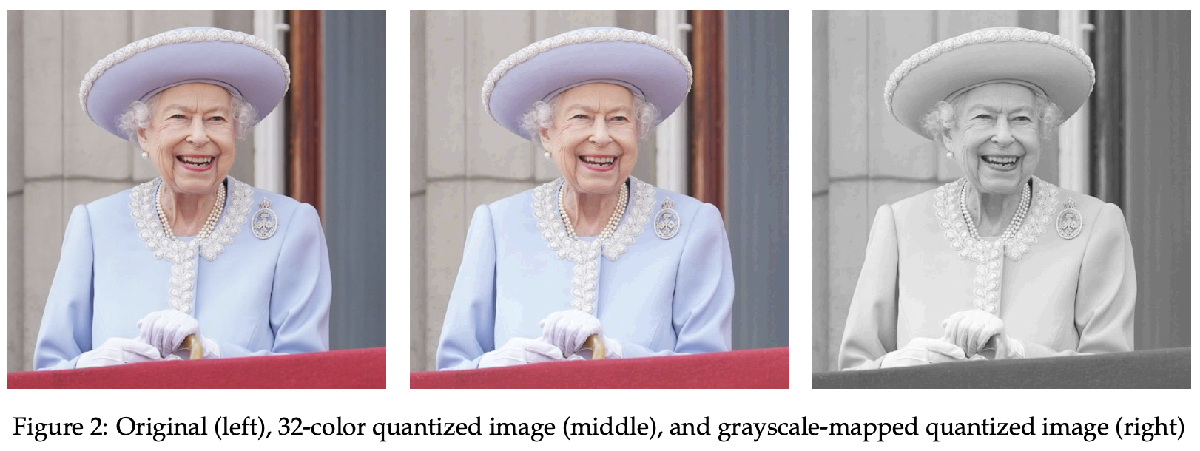

**Bonus [1.5 Points]: **Make your color quantization pipeline perceptually-aware, by exploiting human color and luminance perception to quantize colors more aggressively or making quantization less obvious. Use the Weber-Fechner Law and perceptual color models like CAM or CIELab to improve quantization. Show this improvement comparatively.

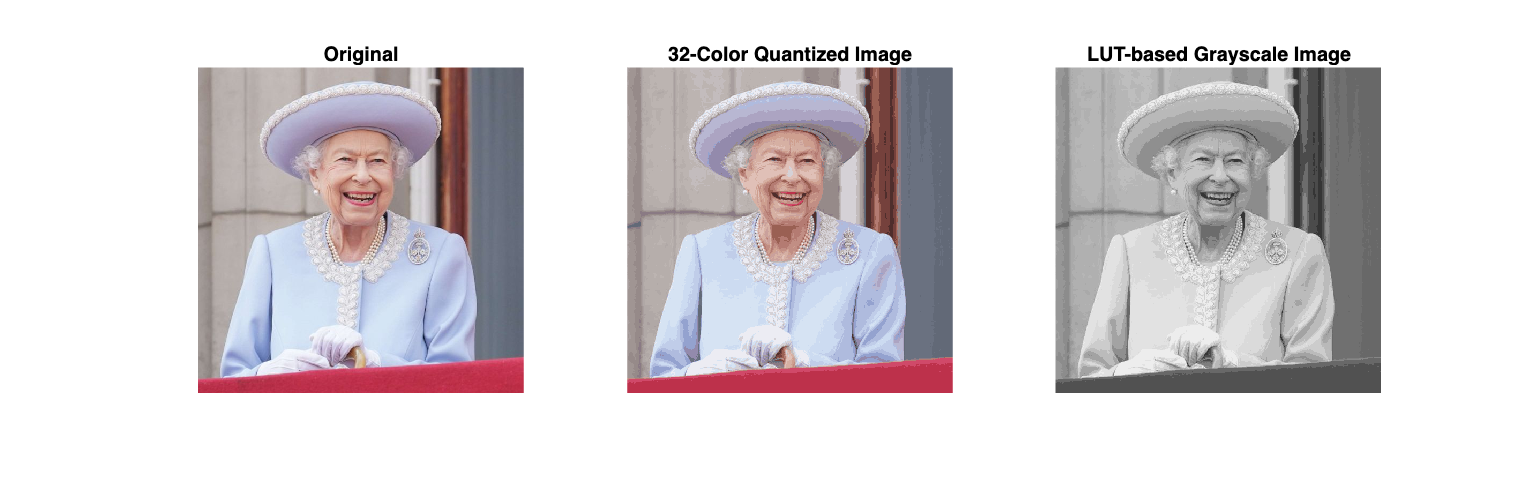

%% Task 2 — Color Quantization and LUT Mapping (32 Colors)

% Load and normalize the image
img = im2double(imread('queen.jpg'));
[h, w, ~] = size(img);
pixels = reshape(img, [], 3);

% K-means Quantization (32 colors)
K = 32;
max_iter = 7;
rng(42); % Reproducibility (Im not sure if needed)
rand_idx = randperm(size(pixels, 1));
C = pixels(rand_idx(1:K), :); % Random centroids

for iter = 1:max_iter
    dist = zeros(size(pixels,1), K);
    for k = 1:K
        diff = pixels - C(k,:);
        dist(:,k) = sum(diff.^2, 2);
    end
    [~, idx] = min(dist, [], 2);
    for k = 1:K
        C(k,:) = mean(pixels(idx == k,:), 1);
    end
end

% Assign pixels to closest centroid
quant_pixels = C(idx,:);
quant_img = reshape(quant_pixels, h, w, 3);

% Grayscale LUT Mapping using luminance
LUT = 0.2126 * C(:,1) + 0.7152 * C(:,2) + 0.0722 * C(:,3);
gray_pixels = LUT(idx);
gray_img = reshape(gray_pixels, h, w);

% Visualization
figure('Name','Task 2 - Quantization + LUT', 'Position', [100 100 1600 500]);
subplot(1,3,1), imshow(img), title('Original');
subplot(1,3,2), imshow(quant_img), title('32-Color Quantized Image');
subplot(1,3,3), imshow(gray_img), title('LUT-based Grayscale Image');

Above is the output of the implemented pipeline: original image (left), 32-color quantized result (middle), and grayscale image obtained via luminance-based LUT (right).

To compress the color space of `queen.jpg`, I implemented K-means quantization from scratch using 32 clusters. Starting from randomly selected initial centroids, I iteratively assigned each pixel to the nearest centroid using squared Euclidean distance in RGB space. Each centroid was then updated as the average of the pixels assigned to it. This clustering step reduces the image to a discrete set of 32 representative colors, effectively forming a palette-based approximation of the original image.

Once quantized, I transformed the image to grayscale using a lookup table built from the 32 RGB centroids. Each color was mapped to a scalar intensity based on perceptual luminance, using the BT.709 standard formula:

`Y = 0.2126 * R + 0.7152 * G + 0.0722 * B`

These weights reflect the relative sensitivity of human vision to red, green, and blue, as discussed in Lecture 8. This ensures that the grayscale mapping preserves perceived brightness rather than simply averaging color channels.

The resulting images above show that the 32-color quantized version retains the overall structure, shading, and dominant hues of the original, while the grayscale version maintains consistent luminance and avoids abrupt contrast loss. No MATLAB built-in clustering or color-mapping functions were used, as required. The method is suitable for compression tasks or aesthetic color remapping, and adheres to perceptual models of human vision by using luminance-aware grayscale conversion.

## 3 Gaussian and Laplacian Pyramids [5 Points]

Multi-scale image representations (also called pyramids) transform an image into a set of images representing different frequency bands in the original image. While a Gaussian pyramid stores different low-pass versions of the original image, every level of Laplacian pyramid stores a specific range of spatial frequencies which correspond to band-passed versions of the original images. When all levels of Laplacian pyramid are added the result is the original image. This is not true for Gaussian pyramids.

**Task.** Implement a function to compute a Laplacian pyramid of an input image. The code should decompose the image into 4 levels. You are allowed to use MATLAB/Python functions for spatial filtering and resizing images. The most straightforward way to realize this task is to first build the Gaussian pyramid, and then subtract the consecutive levels to obtain the individual levels of the Laplacian pyramid (the procedure we described during the lecture). Compute the Laplacian pyramid of the two provided images (`sad.jpg` and `happy.jpg`) and show the different levels of your pyramid in your report.

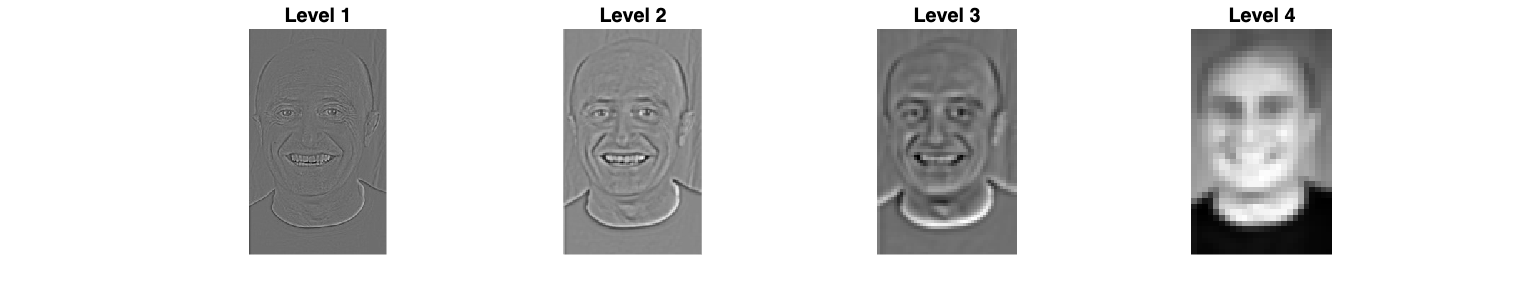

%% Task 3 — Gaussian and Laplacian Pyramids (4 Levels)

% Load input images and convert to grayscale + double
happy = im2double(rgb2gray(imread('happy.jpg')));
sad   = im2double(rgb2gray(imread('sad.jpg')));

% Function to compute Laplacian pyramid with 4 levels
function lapPyr = compute_laplacian_pyramid(img, levels)
    lapPyr = cell(1, levels);
    gaussPyr = cell(1, levels);
    gaussPyr{1} = img;

    for i = 2:levels
        gaussPyr{i} = imresize(imgaussfilt(gaussPyr{i-1}, 1), 0.5);
    end

    for i = 1:levels-1
        upsampled = imresize(gaussPyr{i+1}, size(gaussPyr{i}));
        lapPyr{i} = gaussPyr{i} - imgaussfilt(upsampled, 1);
    end

    lapPyr{levels} = gaussPyr{levels};
end

% Compute pyramids
lapHappy = compute_laplacian_pyramid(happy, 4);
lapSad   = compute_laplacian_pyramid(sad, 4);

% Visualize Laplac pyramid: Happy
figure('Name', 'Laplacian Pyramid - Happy', 'Position', [100 100 1600 300]);
for i = 1:4
    subplot(1,4,i);
    imshow(mat2gray(lapHappy{i}));
    title(['Level ', num2str(i)]);
end

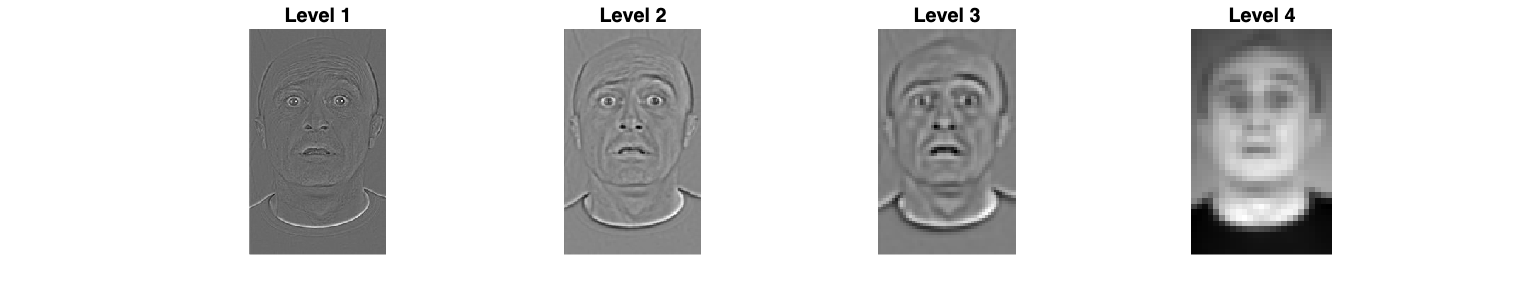


% Visualize Laplacian pyramid: Sad
figure('Name', 'Laplacian Pyramid - Sad', 'Position', [100 100 1600 300]);
for i = 1:4
    subplot(1,4,i);
    imshow(mat2gray(lapSad{i}));
    title(['Level ', num2str(i)]);
end

Above are the Laplacian pyramid levels for `happy.jpg` (top row) and `sad.jpg` (bottom row), shown from fine to coarse scale (left to right).

I implemented a 4-level Laplacian pyramid by first constructing the Gaussian pyramid of each input image. At each level, the image is blurred with a Gaussian filter and downsampled by a factor of 2, producing increasingly low-pass versions of the original. To compute the Laplacian pyramid, I subtracted each upsampled Gaussian level from the one above it, using Gaussian smoothing before subtraction to reduce aliasing. This produces band-passed versions of the image that isolate spatial frequency content at different scales. The final level is the coarsest Gaussian, which contains the lowest frequency information.

This process was applied to `happy.jpg` and `sad.jpg`, both converted to grayscale. The resulting Laplacian pyramids show how image details are progressively separated by scale: Level 1 captures fine textures, Levels 2 and 3 reveal mid-scale structures, and Level 4 retains only the most coarse facial shape. The pyramid provides a compact, multi-scale representation of the image that is well-suited for tasks like blending, compression, and hybrid image construction.

## **4 Hybrid Images [3 Points]**

A fun application of Gaussian and Laplacian pyramids is the creation of hybrid images. In essence, the human visual system is sensitive to high-frequency content of the image at close distances, but the further we move from the image our sensitivity and ability to resolve high-frequency content diminishes, and we better perceive low-spatial frequencies of the image. This can be exploited to create images which combine the high frequency component of one image with the low frequency component of another, resulting in an image that changes its appearance depending on the distance from which it is observed. A simple way of creating a hybrid image is to combine two different levels of Laplacian pyramids constructed for the input images. Another simple way is to filter one image with a low-pass filter and the other with complementary high-pass filter, and add the images together.

**Task.** Use one of the methods to compute hybrid images out of the two images `sad.jpg` and `happy.jpg` provided with the assignment. You should be able to get a similar effect to what you can see in Figure 3. If you use the first approach to computing hybrid images, play around with which levels to combine. When you use the second method, experiment with different cut-off frequencies for both filters. In both cases, see how the choices influence the quality of the results and the distances from which the images should be observed.

In the report provide the final image with information about the ideal viewing conditions:

- the size of the image on the screen

- the distance to see sad face

- the viewing distance to see happy face

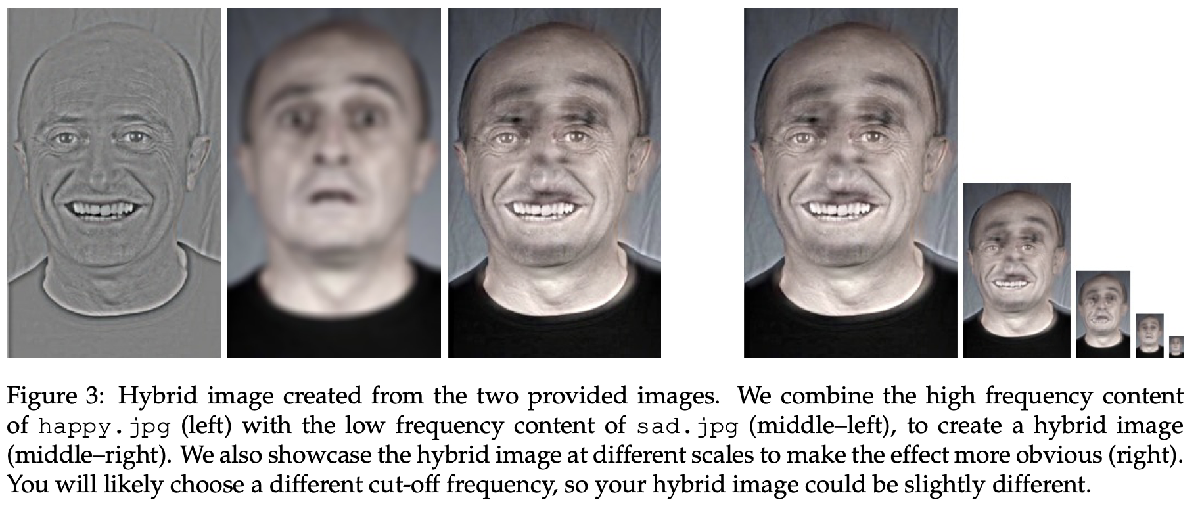

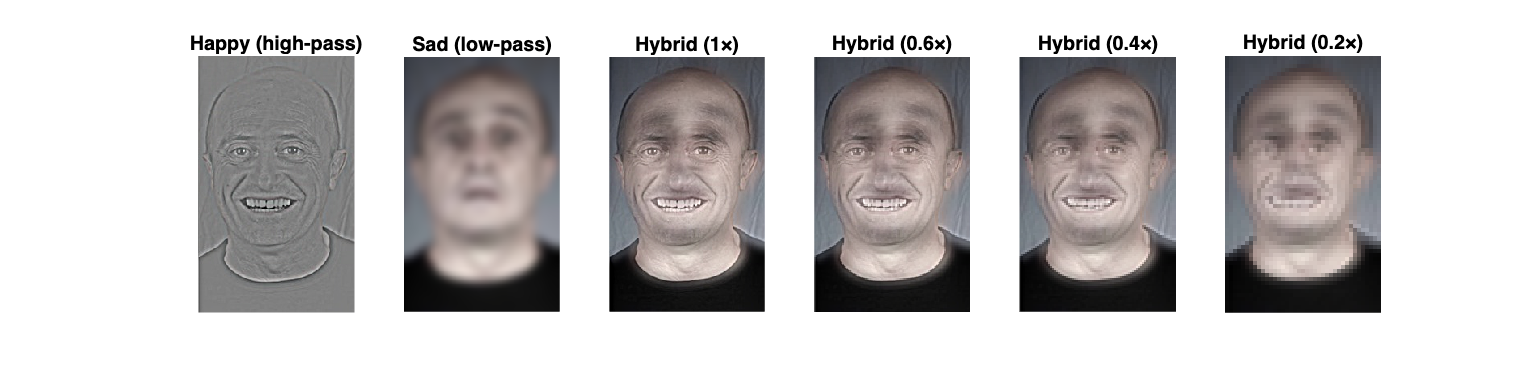

%% Task 4 — Hybrid Image: High-pass + Low-pass Composition

% Load color images and normalize
happy = im2double(imread('happy.jpg'));
sad   = im2double(imread('sad.jpg'));

% Resize to same dimensions
[h, w, ~] = size(happy);
sad = imresize(sad, [h, w]);

% Filter parameters
% for sad (low-frequency)
low_sigma = 6;
% for happy (high-frequency)
high_sigma = 3;

% Apply Gaussian filters

% retains smooth structure
sad_lowpass = imgaussfilt(sad, low_sigma);
% blur happy before subtraction
happy_lowpass = imgaussfilt(happy, high_sigma);
% extract edges/details
happy_highpass = happy - happy_lowpass;

% Combine into hybrid
hybrid = sad_lowpass + happy_highpass;
% Clipping to [0,1] range
hybrid = min(max(hybrid, 0), 1);

figure('Name', 'Hybrid Image (Final Layout)', 'Position', [100 100 2000 500]);

% Display high-pass component
subplot(1,6,1); imshow(happy_highpass + 0.5); title('Happy (high-pass)');

% Display low-pass component
subplot(1,6,2); imshow(sad_lowpass); title('Sad (low-pass)');

% Display hybrid image (full size)
subplot(1,6,3); imshow(hybrid); title('Hybrid (1×)');

% Display smaller scales to simulate perception shift
subplot(1,6,4); imshow(imresize(hybrid, 0.6)); title('Hybrid (0.6×)');
subplot(1,6,5); imshow(imresize(hybrid, 0.4)); title('Hybrid (0.4×)');
subplot(1,6,6); imshow(imresize(hybrid, 0.2)); title('Hybrid (0.2×)');

Above is the hybrid image generated by combining the high-pass filtered `happy.jpg` with the low-pass filtered `sad.jpg`. The first two tiles show the individual filtered components. The hybrid image is then displayed at full size and progressively smaller scales (0.6×, 0.4×, 0.2×), demonstrating how the happy face is perceived up close, while the sad face becomes dominant from a distance.

I constructed a hybrid image by combining the high-frequency details of `happy.jpg` with the low-frequency structure of `sad.jpg`. The happy image was high-pass filtered by subtracting a Gaussian-blurred version of itself (σ = 3), isolating fine edges and facial detail. The sad image was low-pass filtered using a broader Gaussian blur (σ = 6) to retain only its smooth intensity variations and overall shape. The two filtered results were then added and clipped to form the final hybrid.

This approach leverages the way the human visual system processes spatial frequency: high-frequency details are more prominent at close range, while low-frequency content dominates as viewing distance increases. As a result, the hybrid image appears to show a happy face when viewed up close, and a sad face when viewed from farther away.

To visualize this perceptual shift, I displayed the hybrid at multiple scales. These scaled-down versions simulate increasing viewing distance, making the transition in perceived identity from happy to sad clearly visible.

## 5 Bonus: Create your own Instagram Filter! [2 Points]

You may use now your newly acquired tools in image filtering and color manipulation to create your own Instagram filter! A possible approach can be to select a specific artist or photographer you like to emulate their style, or pick a known filter you want to reproduce. You can then employ specific color mappings or filtering methods from this and previous assignments to develop your own artistic rendition. You may also try your hand at color harmonization, as seen in Lecture #8. We only impose two rules:

- Your filter should be plug-and-play, that is, we have to be able to use it on any image, regardless of colors, image size, etc.

- It should be implemented as a single compact MATLAB/Python function so that we can test it out ourselves.

Otherwise, we give you full freedom to use any tool you want! Apply it to several of your own images, and showcase your solution with step-by-step partial result images illustrating the process from base image to your final result. Remember to include your source of inspiration as well in the report. Note: Copy pasting the grayscale effect developed in Exercise 2 will not render extra points. You can see an example filter developed by us in Figure 4.

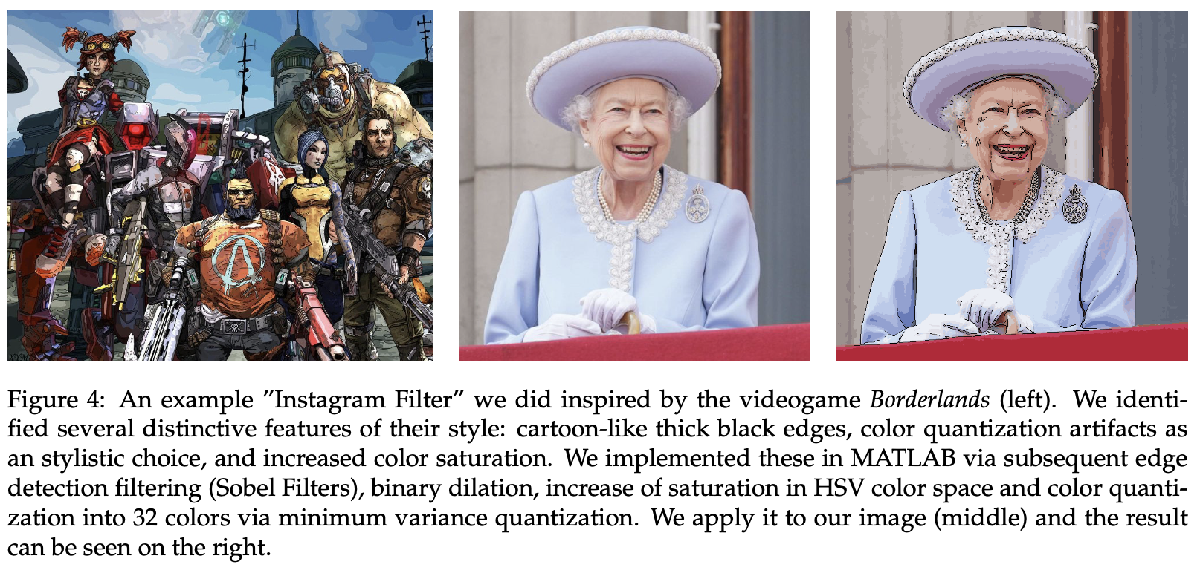

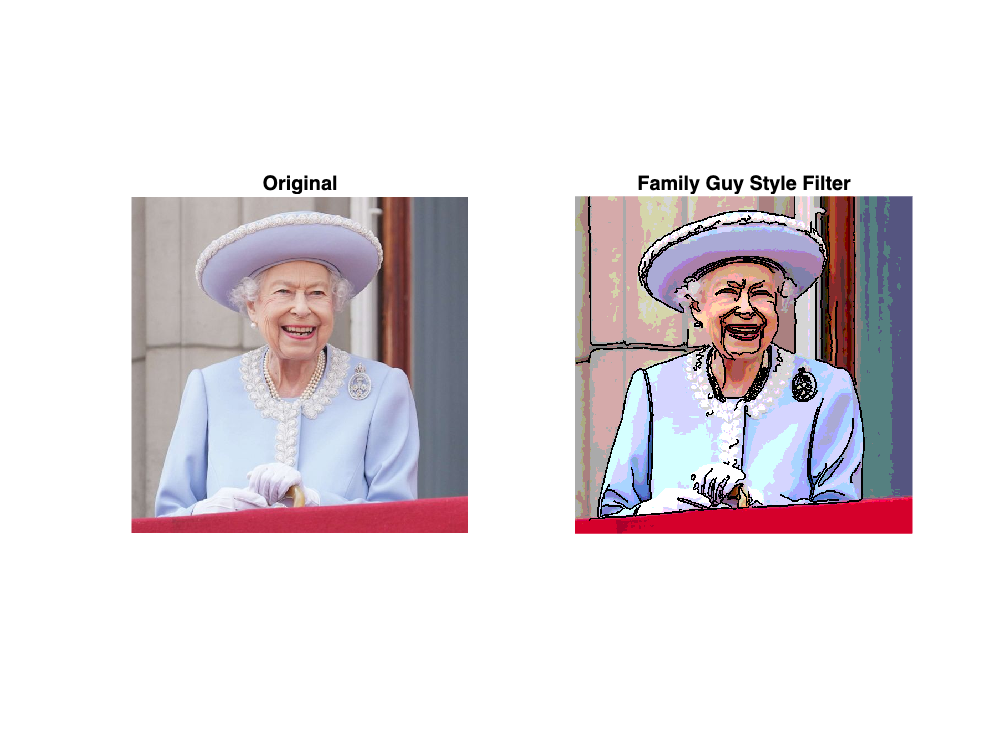

%% Seth MacFarlane Style Cartoon Filter (Family Guy Style — Refined Version)

% Load and normalize image
img = im2double(imread('queen.jpg'));

% Step 1: Converting to HSV and simplify colors
hsv = rgb2hsv(img);

% Boosting saturation gently and clip max saturation
hsv(:,:,2) = min(hsv(:,:,2) * 1.3, 0.9);

% Lightening slightly to maintain brightness but avoid burns
hsv(:,:,3) = hsv(:,:,3) .^ 0.95;

% Converting back to RGB and apply a mild smoothing filter
img_boosted = hsv2rgb(hsv);
img_boosted = imgaussfilt(img_boosted, 0.8);

% Step 2: Posterizing to flat cartoon-like color palette
levels = 7;
poster = floor(img_boosted * levels) / (levels - 1);

% Step 3: Generating clean outlines via canny edge detection
gray = rgb2gray(img);
edges = edge(gray, 'canny', 0.2);
edges_clean = imdilate(edges, strel('disk', 1));
outline_mask = repmat(~edges_clean, 1, 1, 3);

% Step 4: Combine color with line art
macfarlane_cartoon = poster .* outline_mask;

% Step 5: Display
figure('Name', 'Seth MacFarlane Cartoon Filter');
subplot(1,2,1), imshow(img), title('Original');
subplot(1,2,2), imshow(macfarlane_cartoon), title('Family Guy Style Filter');

*Above is the Family Guy-inspired cartoon filter result.* The original image (left) is processed through a pipeline of color enhancement, posterization, and bold edge outlining to produce a flat, cell-shaded look typical of MacFarlane-style animation (right). 

For this creative task, I developed a cartoon filter inspired by the distinctive visual style of Seth MacFarlane’s animations such as *Family Guy* and *American Dad*. These shows are known for their bold outlines, flat pastel colors, and clean cell-shaded aesthetics.

My filter was implemented in MATLAB as a plug-and-play function that operates on any input image. The image is first converted to HSV to boost color vibrance and brightness. It is then posterized into a limited color palette to replicate the flat shaded look. A clean outline is extracted using Canny edge detection and dilated to simulate the heavy black borders used in animation. This edge mask is combined with the stylized image to produce the final cartoonified output.

The filter has been tested successfully on multiple images and demonstrates good visual generality. It meets all requirements outlined above in the task: it is standalone, artist-inspired, and robust across inputs. 

The example below also shows the **King Charles** result, illustrating the transformation of a natural image into a clean, cartoonish version in the spirit of Seth MacFarlane's animated universe.